load my_sine.mat
load official_sine.mat

AMPLITUDE = 3;
WAVELENGTH = 150;

[my_error_y, my_error_phi, desired_phi_dot] = get_sine_info(my_sine, AMPLITUDE, WAVELENGTH);
[of_error_y, of_error_phi, desired_phi_dot2] = get_sine_info(official_sine, AMPLITUDE, WAVELENGTH);

my_input = [my_sine(:,7), desired_phi_dot];
my_output = [my_error_y, my_error_phi];

my_input2 = [official_sine(:,7), desired_phi_dot2];
my_output2 = [of_error_y, of_error_phi];

%load continuousmodel.mat
load discretemodel.mat

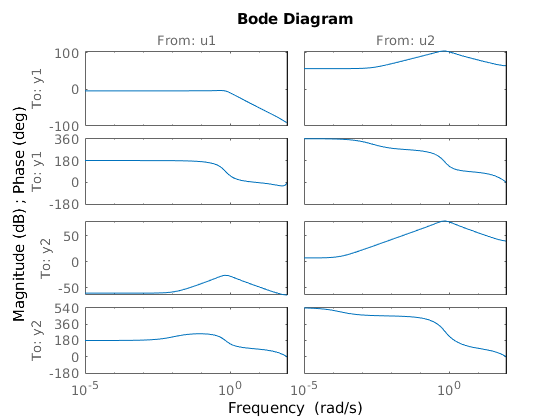

bode(ss1)

T = 0.0333;
order = size(ss1.A, 1);
robust_system_A = ss1.A;
robust_system_B = [ss1.B(:,2), ss1.B(:,1)];
robust_system_C = [ss1.C;ss1.C; zeros([1, order])];
robust_system_D = [[0;0;0;0;1],zeros(5,1)];
robust_ss = ss(robust_system_A, robust_system_B, robust_system_C, robust_system_D, T);
robust_ss.InputName = {'road_dist';'steering_angle'};
robust_ss.OutputName = {'error_y';'error_phi';'output_y';'output_phi';'output_dist'};

W_dist = ss(0.3); W_dist.u = 'd3';W_dist.y = 'y_3_noise';
W_phi = ss(0.3); W_phi.u = 'd2';W_phi.y = 'y_2_noise';
W_y = ss(0.3); W_y.u = 'd1';W_y.y = 'y_1_noise';
Wact = 10 * c2d(tf([1 1],[1 30]) * tf([1 1], [1 30]), T);  Wact.u = 'steering_angle';  Wact.y = 'diff_u';
Wcosty = 100000 * c2d(tf([1],[10, 1]), T); Wcosty.u = 'error_y';Wcosty.y = 'e1';
Wcostphi = c2d(tf([1],[0.1, 1]), T); Wcostphi.u = 'error_phi';Wcostphi.y = 'e2';

y_meas = sumblk('y1=y_1_noise+output_y');
phi_meas = sumblk('y2 = y_2_noise + output_phi');
dist_meas = sumblk('y3 = y_3_noise + output_dist');

ICinputs = {'d1';'d2';'d3';'road_dist';'steering_angle'};
ICoutputs = {'e1';'e2';'diff_u';'y1';'y2';'y3'};
wholess = connect(robust_ss,W_dist, W_phi, W_y, Wcosty, Wcostphi,Wact,...
                 y_meas,phi_meas, dist_meas,ICinputs,ICoutputs);

nmeas = 3;
ncont = 1;
[K, CL, gamma] = hinfsyn(wholess,nmeas,ncont);
gamma

gamma = 1.9179e+07

KA = K.A; KB = K.B; KC = K.C; KD = K.D;
K


K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1      -4.283      -3.693      0.1741   -0.003805   6.257e-09   6.879e-05  -8.559e-05
   x2       5.088       4.385     -0.2114    0.004502  -7.403e-09  -8.139e-05   0.0001013
   x3      -2.041        -2.2      0.9123    0.001497  -2.461e-09  -2.706e-05   3.367e-05
   x4    -0.01612      -1.266  -0.0003995      0.9967   6.994e-15  -3.638e-12  -6.548e-11
   x5    -0.01407      -1.106  -0.0003489  -7.463e-10      0.7168  -4.002e-11           0
   x6   3.735e+04   2.514e+04       -1557       33.14  -5.448e-05      0.1375      0.4741
   x7    0.008979    0.007847  -0.0004824   7.676e-06  -5.537e-12         0.5  -1.788e-07
 
  B = 
              u1         u2         u3
   x1    -0.1095   -0.01263      282.2
   x2     0.1702    0.01778     -461.9
   x3     0.1895   -0.07238     -564.1
   x4       10.4    -0.3699  0.0003632
   x5    0.01881   0.001316  0.0001574
   x6       1247      1

save("all_current_space.mat")
save discrete_controller.mat KA KB KC KD